clc; clear; close all
cd 'E:\Machine Learning\NW_image_quality_50tests_noramlized\test\5'
addpath 'F:\research\deep learning\deep_learning_images\SiNW_and_AgNW\test'
addpath 'E:\Jiaxu Flashdrive Backup\code\functions'
addpath 'F:\research\deep learning\deep_learning_images\Quality Est'

imds = imageDatastore("E:\Machine Learning\NW_image_quality_50tests\test\5");

for i = 1:length(imds.Files)
    I(:,:,i) = readimage(imds,i);
end

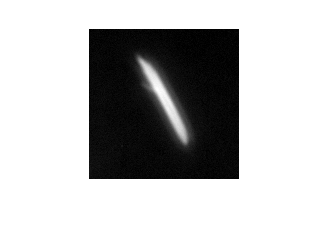

float_I = double(I);
scale_I = scale_image(float_I);
imshow(scale_I(:,:,round(rand(1)*50)));

for i = 1:length(imds.Files)
    rgb_I = cat(3,scale_I(:,:,i),scale_I(:,:,i),scale_I(:,:,i));
    imwrite(rgb_I...
        ,sprintf('E:\\Machine Learning\\NW_image_quality_50tests_rgb\\test\\5\\%d.jpeg',i));
end

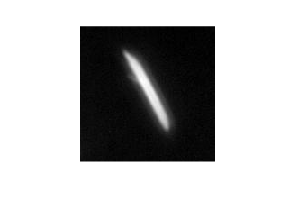

img = imread("2.jpeg");
imshow(img)